# Tuning ottimale controllore PID - joint2

### Caricamento modelli dei processi

clear all; clc; close all

Aggiungo opzione per evitare la molteplicità di 360° nella base.

bode_opts = bodeoptions('cstprefs');
bode_opts.PhaseWrapping = 'on';

 Carico il modello.

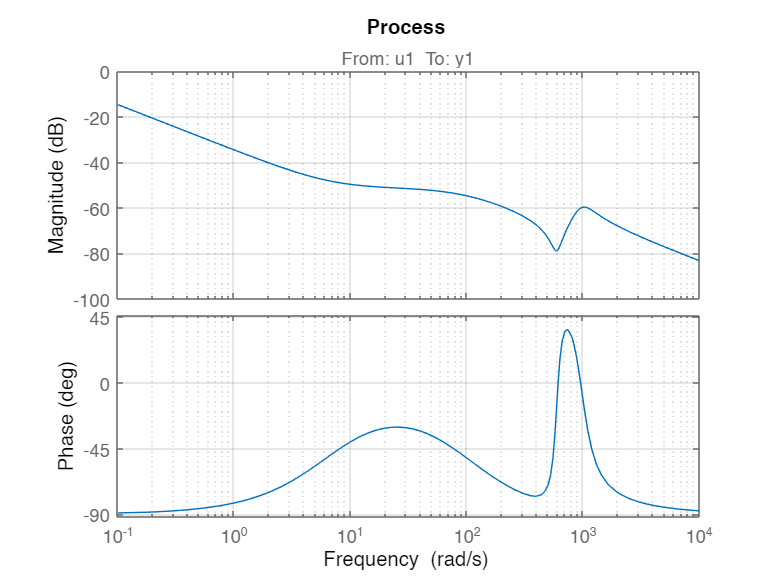

load modello_j2.mat

process = modello_continuo_tf_j2;
figure
bodeplot(process)
grid on; title('Process');

Scelta dell'intervallo di frequenze d'interesse

w_inf = 1;
w_sup = 10^4;

#### Inner loop: output Filtered **P **


$$C_2(s)=K_p \cdot \frac{1}{T_{fu}s+1}$$


Cifra di merito da minimizzare:


$$J=\left( \omega_c - \omega_{c,des}\right)^2$$


- $\omega_c$: frequenza (pulsazione) di taglio

- $\omega_{c,des}$: valore desiderato

Le incognite del problema sono $x=[K_p, \; K_i, \; K_d, \; T_{fd}, \; T_{fu}]$ (alcune verranno forzate a 0, se non vogliamo utilizzarle).

internal_joint1.wc_des = 300;    % pulsazione di taglio desiderata

% funzione che restituisce il valore di J in funzione di x
J = @(x)pid_filt_cost_function(x,process,internal_joint1.wc_des,0);

#### Vincoli

- Massima sensitività $MS$ per garantire la robustezza (1.4 molto robusto, 2 poco robusto ma aggressivo)

- La funzione di anello chiuso $F$ deve avere modulo limitato per $\omega\geq\omega_h$

- La funzione fra disturbo sul carico e l'uscita deve modulo limitato per $\omega\leq\omega_l$

- Il margine di fase deve essere almeno 60°

Definizione dei vincoli

% Massima sensitività
internal_joint1.MS = 2;

% Reiezione disturbo di misura
internal_joint1.wh = 2000;
internal_joint1.Fh_max = 0.1;

% Reiezione disturbo sul carico
internal_joint1.wl = 10;
internal_joint1.Dl_max = 0.1;

% Minimo margine di fase tollerabile
internal_joint1.PM_min = 60;

Per calcolare in maniera corretta $MS$ passo alla funzione anche il vettore delle pulsazioni naturali che voglio testare.

w_vector = logspace(log10(w_inf),log10(w_sup))';
w_vector = sort(unique([w_vector;internal_joint1.wl;internal_joint1.wh]));

Funzione per vincoli non lineari

nlcon = @(x)pid_filt_constraints(x, process, w_vector, ...
                                 internal_joint1.MS, internal_joint1.wh, internal_joint1.Fh_max, ...
                                 internal_joint1.wl, internal_joint1.Dl_max, internal_joint1.PM_min,0);

### Ottimizzatore interno

timeout = 60*2;
% [valore iniziale, limite inferiore, limite superiore]
internal_joint1.aKp = [500, 100, 10000];
internal_joint1.aKi = [0, 0, 0];
internal_joint1.aKd = [0, 0, 0];
internal_joint1.aTfd = [0, 0, 0];
internal_joint1.aTfu = [1/300, 1/500, 1/40];

x0 = [internal_joint1.aKp(1), internal_joint1.aKi(1), internal_joint1.aKd(1), internal_joint1.aTfd(1), internal_joint1.aTfu(1)];
    
problem = createOptimProblem('fmincon','x0',x0, ...
                                 'objective',J, ...
                                 'lb',[internal_joint1.aKp(2), internal_joint1.aKi(2), internal_joint1.aKd(2), internal_joint1.aTfd(2), internal_joint1.aTfu(2)], ...
                                 'ub',[internal_joint1.aKp(3), internal_joint1.aKi(3), internal_joint1.aKd(3), internal_joint1.aTfd(3), internal_joint1.aTfu(3)], ...
                                 'nonlcon',nlcon);

solver = GlobalSearch('Display','iter','MaxTime',timeout);
x = run(solver,problem)

 Num Pts                 Best       Current    Threshold        Local        Local                 
Analyzed  F-count        f(x)       Penalty      Penalty         f(x)     exitflag        Procedure
       0       97       59.47                                   59.47            1    Initial Point
     200     1377       59.47                                   59.47            1    Stage 1 Local
     300     1479       59.47          8469        124.4                              Stage 2 Search
     400     1579       59.47          7317          311                              Stage 2 Search
     500     1679       59.47     1.083e+04        775.4                              Stage 2 Search
     600     1779       59.47     1.608e+04         1931                              Stage 2 Search
     700     1879       59.47          1269        309.3                              Stage 2 Search
     800     1979       59.47          5213          771                              Stage 2 S

x = 	1.0e+03 *

    2.0346         0         0         0    0.0000


% solver = MultiStart('Display','iter','MaxTime',timeout,'UseParallel',true);
% addAttachedFiles(gcp,["pid_filt_constraints.m" "pid_filt_cost_function.m"]) % Usare se si abilita il pool parallelo su un Cluster online
% n_startingPoints = 50;
% x = run(solver,problem,n_startingPoints)

s=tf('s');
Kp = x(1);
Tfu = x(5);
Cv_joint2 = Kp*1/(Tfu*s+1);
Cv_joint2.InputName = 'sp-vel';
Cv_joint2.OutputName = 'torque';

Loop_int_joint2 = process*Cv_joint2;

figure;
subplot(1,2,1)
margin(Loop_int_joint2)
grid on;

subplot(1,2,2)
bodemag(feedback(1,Loop_int_joint2))
title('Sensitivity Function')
getPeakGain(feedback(1,Loop_int_joint2))

ans = 1.3030

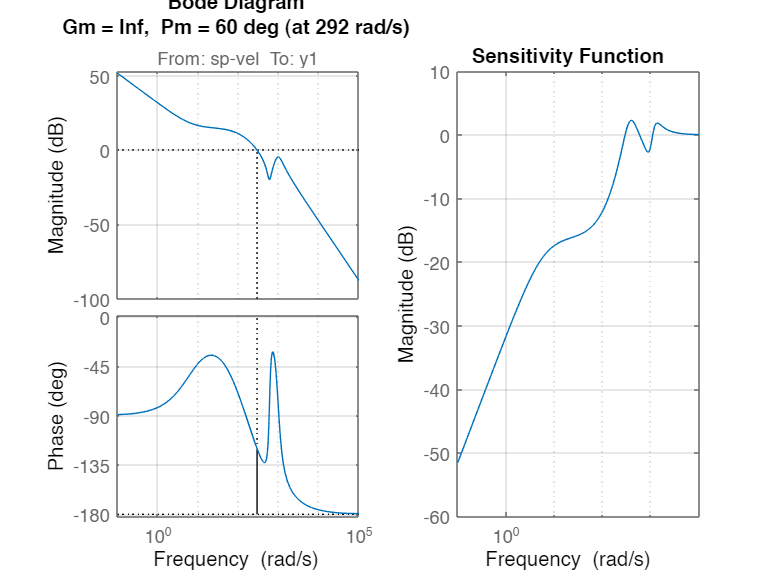

grid on

### Loop esterno: PI

Processo da controllare (velocità → posizione) visto dal controllore esterno: serie tra la funzione di anello chiuso del loop interno e l'integratore (necessario per passare da velocità a posizione).


$$P_{\textrm{ext}} =\frac{C_v \cdot P}{1+C_v \cdot P}\cdot \frac{1}{s}$$


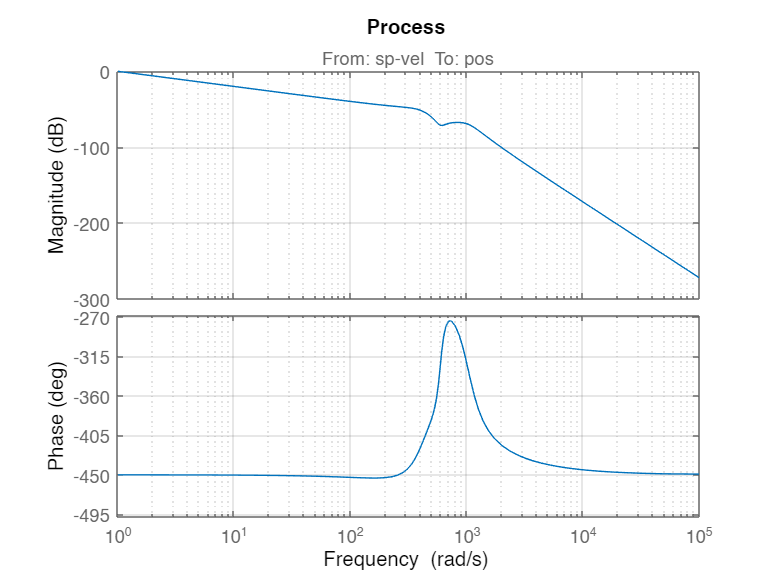

process_ext = minreal(feedback(Loop_int_joint2,1)*1/s);
process_ext.InputName = 'sp-vel';
process_ext.OutputName = 'pos';
figure
bodeplot(process_ext)
grid on; title('Process');

external_joint1.wc_des = 300;    % pulsazione di taglio desiderata

% funzione che restituisce il valore di J in funzione di x
J = @(x)pid_filt_cost_function(x,process_ext,external_joint1.wc_des,0);

### Vincoli

Definizione dei vincoli

% Massima sensitività
external_joint1.MS = 2;

% Reiezione disturbo di misura
external_joint1.wh = 2000;
external_joint1.Fh_max = 0.1;

% Reiezione disturbo sul carico
external_joint1.wl = 10;
external_joint1.Dl_max = 1;

% Minimo margine di fase tollerabile
external_joint1.PM_min = 60;

w_vector = logspace(log10(w_inf),log10(w_sup))';
w_vector = sort(unique([w_vector;external_joint1.wl;external_joint1.wh]));

nlcon = @(x)pid_filt_constraints(x, process_ext, w_vector, ...
                                 external_joint1.MS, external_joint1.wh, external_joint1.Fh_max, ...
                                 external_joint1.wl, external_joint1.Dl_max, external_joint1.PM_min,0);

### Ottimizzatore esterno

timeout = 60*2;
% [valore iniziale, limite inferiore, limite superiore]
external_joint1.aKp = [268, 0.01, 2000];
external_joint1.aKi = [1/200, 1/1000, 100];
external_joint1.aKd = [0.01, 0.001, 3];
external_joint1.aTfd = [100, 0.1, 500];
external_joint1.aTfu = [1/600, 1/1000,1/200];

x0 = [external_joint1.aKp(1), external_joint1.aKi(1), external_joint1.aKd(1), external_joint1.aTfd(1), external_joint1.aTfu(1)];
    
problem = createOptimProblem('fmincon','x0',x0, ...
                                 'objective',J, ...
                                 'lb',[external_joint1.aKp(2), external_joint1.aKi(2), external_joint1.aKd(2), external_joint1.aTfd(2), external_joint1.aTfu(2)], ...
                                 'ub',[external_joint1.aKp(3), external_joint1.aKi(3), external_joint1.aKd(3), external_joint1.aTfd(3), external_joint1.aTfu(3)], ...
                                 'nonlcon',nlcon);

%solver = GlobalSearch('Display','iter','MaxTime',timeout);
%x = run(solver,problem)
opt1=optimoptions("ga","MaxTime",3600*2,'InitialPopulation',x0,'Display','iter');
x1=ga(J,5,[],[],[],[],[external_joint1.aKp(2), external_joint1.aKi(2), external_joint1.aKd(2), external_joint1.aTfd(2), external_joint1.aTfu(2)] ...
    ,[external_joint1.aKp(3), external_joint1.aKi(3), external_joint1.aKd(3), external_joint1.aTfd(3), external_joint1.aTfu(3)] ...
    ,nlcon,opt1);


Single objective optimization:
5 Variable(s)
4 Nonlinear inequality constraint(s)

Options:
CreationFcn:       @gacreationuniform
CrossoverFcn:      @crossoverscattered
SelectionFcn:      @selectionstochunif
MutationFcn:       @mutationadaptfeasible

                              Best       Max        Stall
Generation  Func-count        f(x)     Constraint  Generations
    1           2500   5.08835e-12            0      0
    2           4950   2.98612e-22            0      0
    3           7400   2.98612e-22            0      1
    4           9850   1.16322e-25            0      0
    5          12300   1.16322e-25            0      1
Optimization terminated: average change in the fitness value less than options.FunctionTolerance
 and constraint violation is less than options.ConstraintTolerance.



% solver = MultiStart('Display','iter','MaxTime',timeout,'UseParallel',true);
% addAttachedFiles(gcp,["pid_filt_constraints.m" "pid_filt_cost_function.m"]) % Usare se si abilita il pool parallelo su un Cluster online
% n_startingPoints = 50;
% x = run(solver,problem,n_startingPoints)

s=tf('s');
Kp = x(1);
Ki = x(2);
Tfu = x(5);
Cp_joint2 = (Kp+Ki/s)*1/(Tfu*s+1);
Cp_joint2.InputName = 'sp-vel';
Cp_joint2.OutputName = 'pos';


Loop_int_joint2 = process_ext*Cv_joint2;

figure;
subplot(1,2,1)
margin(Loop_int_joint2)
grid on;

subplot(1,2,2)
bodemag(feedback(1,Loop_int_joint2))
title('Sensitivity Function')
getPeakGain(feedback(1,Loop_int_joint2))

ans = 1

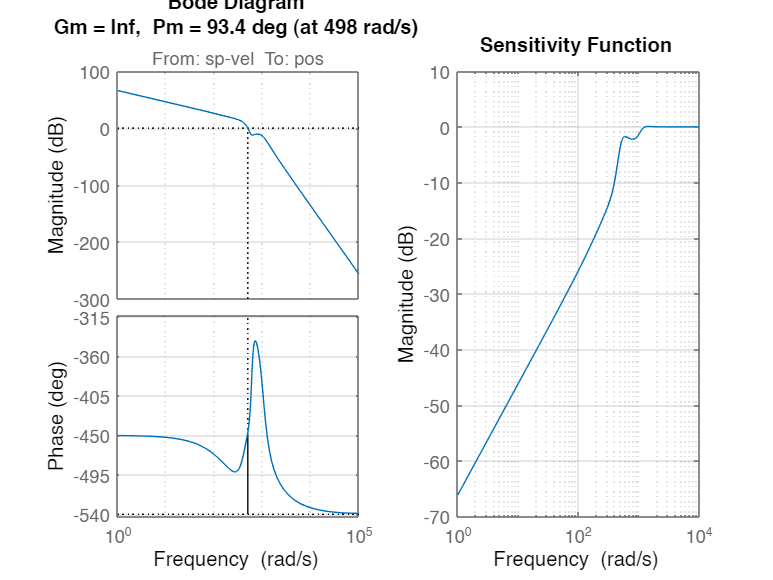

grid on

save parameters_controller_ext_joint2 x1
save parameters_controller_int_joint2 x